# Universidade Federal de Campina Grande

# Programa de Pós-Graduação em Engenharia Elétrica

# Estimação e Identificação de Sistemas - 21.2

## Professores: Antonio Marcus Nogueira Lima, Dr.

##                        **Saulo** Oliveira **Dornellas** Luiz, Dr.

## Aluno: Arthur Dimitri Brito Oliveira

## Relatório de Atividade I - Estimação de Parâmetros

Este documento tem como objetivo descrever o procedimento para caracterizar a função de transferência de um sistema a partir do espectro. 

## Sumário

- Introdução

-     O problema Arquétipo - Modelos ARX e o Método de Mínimos Quadrados

- Desenvolvimento

- Avaliação Teórica - Erro de Estimação

-         Modelo I

-         Modelo II

- Experimentos

- Referências 

## Introdução

Inferir modelos a partir de observações e estudar suas propriedades tem grande relação com o que é o método científico. A identificação de sistemas lida com o desafio de construir modelos matemáticos de sistemas dinâmicos baseado nos dados coletados. Assim, ao interagir com o sistema, é necessário assumir uma relação entre os sinais observados. Isto é, é necessário possuir um modelo do sistema. Tais modelos variam de acordo com o formalismo matemático. 

Os sistemas reais diferem de modelos matemáticos. Pode-se comparar determinados aspectos do sistema físico com sua descrição matemática, mas é impossível estabelecer uma conexão exata entre eles. Sendo assim, a decisão de adotar, ou não, um modelo deve ser, majoritariamente, guiada pela sua usabilidade, mais do que pela sua exatidão. 

### O problema Arquétipo - Modelos ARX e o Método de Mínimos Quadrados

Um sistema pode ser denotado por uma equação de diferença linear entre a saída $y(t)$ e a entrada $u(t)$:


$$y(t) + a_1y(t-1) + \: ... \: +a_n(t-n) = b_1u(t-1) + \:...\: +b_mu(t-m)$$


Ou seja, dada as observações passadas, é possível determinar o próximo valor de saída. Assim: 


$$y(t) = -a_1y(t-1) + ... + -a_n(t-n)+b_1u(t-1)+...+b_mu(t-m)$$


Em uma notação mais compacta, a saída pode ser expressa como:


$$y(t) = \varphi^T(t)\theta = \left[\matrix{-y(t-1) \:...\:-y(t-n) \: u(t-1) \: ... \:u
(t-m)}\right ] \left[\matrix{a_1 \cr ... \cr a_n \cr b_1 \cr ... \cr b_m}\right]$$


Supondo que não se sabe o valor dos parâmetros $\theta$  e que em um intervalo $1\leq t \leq N$ conhece-se os valores da entrada e da saída por meio do vetor de dados $Z^N=[u(1),y(1) ... \: ...u(N),y(N)]$, pode-se utilizar a formulação do problema de mínimos quadrados para determinar o valor ótimo para os parâmetros $\hat \theta$. Assim,


$$v_N(\theta,Z^N) = \frac{1}{N}\sum_{t=1}^{N}(y(t)-\hat y(t|\theta))^2 = \frac{1}{N}\sum_{t=1}^{N}[y(t)-\varphi^T(t)\theta]^2$$



$$\min_\theta V_N(\theta,Z^N)$$


Ao derivar em relação ao $\theta$, igualar a zero encontra-se que a aproximação para o vetor de parâmetros pode ser dada por:


$$\hat \theta = \left [\sum_{t=1}^{N}\varphi(t)\varphi^T(t)\right]^{-1}\sum_ {t=1}^{N} \varphi(t)y(t)$$


O vetor $\varphi$ é composto pelos regressores, e este termo faz alusão ao fato de que tenta-se calcular a saída com base nos dados prévios do sistema. Supondo que os dados obtidos a partir de medições sejam contaminados por um ruído branco $e(t)$ com variância $\lambda$ e média nula, a saída pode ser reescrita como:


$$y(t) = \varphi^T(t)\theta_0 + e(t)$$


Substituindo na expressão de aproximação de $\hat \theta$, tem-se:

        $\hat\theta_N = \left [\sum_{t=1}^{N}\varphi(t)\varphi^T(t) \right ]^{-1} \left[\sum_ {t=1}^{N}\varphi(t)\varphi^T(t)\theta_0 + \sum_{t=1}^{N}\varphi(t)e(t)\right] = R(N)^{-1} \left[\sum_ {t=1}^{N}\varphi(t)\varphi^T(t)\theta_0 + \sum_{t=1}^{N}\varphi(t)e(t)\right] $        (1)

Sendo assim, o erro na estimação dos parâmetros do vetor $\hat \theta_N$ pode ser expresso por:


$$\tilde \theta_N = \hat \theta-\theta_0 = R(N)^{-1}\sum_{t=1}^{N}\varphi(t)e(t) $$


Pode-se, então, tomar o valor esperado do erro de estimação dos parâmetros:


$$E(\tilde \theta_N)= \hat \theta-\theta_0 = R(N)^{-1}\sum_{t=1}^{N}\varphi(t)E(e(t)) = 0$$


## Desenvolvimento

Dados dois sistemas na forma:


$$\sigma_1: y_1 = \frac{q^{-1}}{1-0.8q^{-1} }u + \frac{q^{-1} }{1-0.8q^{-1}}e$$



$$\sigma_2 :y_2 = \frac{q^{-1}}{1-0.8q^{-1} }u + e$$


Onde $e $~$N(0,1) $ e $u$~$N(0,1) $. Reescrevendo, tem-se que a primeiro sistema pode ser escrito como:


$$y(t)(1-0.8q^{-1})=(u(t) + e(t))q^{-1} $$



$$\sigma_1: y(t) = u(t-1) +0.8y(t-1) + e(t-1)$$


O segundo sistema pode ser expresso por:


$$y(t)(1-0.8q^{-1}) = u(t)q^{-1} + e(t)(1-0.8q^{-1} )$$



$$\sigma_2: y(t) = u(t-1) +0.8y(t-1) + e(t) - 0.8e(t-1) $$


### Avaliação Teórica - Erro de Estimação

Tendo acesso aos modelos $\sigma_1$ e $\sigma_2$, é possível traçar expectativas teóricas quanto ao erro de estimação para cada um deles. Tais expectativas devem ser condizentes com as simulações realizadas na seção Experimentos. 

#### Modelo I

Analisando o primeiro modelo, da esperança do erro de estimativa dos parâmetros é dada por:

        $E\tilde \theta_N = E\left[R(N)^{-1} \sum_{t=1}^{N}\varphi(t)e(t)\right] = R(N)^{-1} \sum_{t=1}^{N}\varphi(t)Ee(t) = 0$        (2)

Como o erro $e(t)$ tem média nula, é evidente que a estimativa independe do erro. Além disso, se a matriz de covariância da entrada $\bar R$ for não-singular, a matriz de covariância da estimativa dos parâmetros é dada por: 


$$P_N = E\tilde \theta_N \tilde \theta_N^T = ER(N)^{-1} \sum_ {t,s=1}^{N}\varphi(t)e(t)e(s)\varphi^T(s)R(N)^{-1} $$


Utilizando o fato que $E e(t)e(s) = \lambda \sigma(t-s)$, tem-se que:


$$P_N = \lambda R(N)^{-1} $$


A matriz de covariância do erro de estimação é determinada, inteiramente, pelas propriedades da matriz $R(N) $ e o nível de ruído $\lambda$. Definindo $\bar R$ como sendo:


$$\bar R = \lim_{N \rightarrow \infty}\frac{1}{N}R(N)$$


Caso a matriz $\bar R$ seja não singular, a matriz de covariância da estimação de parâmetros é dada, aproximadamente, por:

     $P_N = \frac{\lambda}{N}\bar R^{-1} $     (3)

Isso significa que a aproximação dos parâmetros tende a melhorar com o tempo quando o erro é do tipo gaussiano, de tal forma que a matriz de covariância torna-se cada vez menor. 

#### Modelo II

No caso do modelo $\sigma_2$, o ruído é uma soma ponderada de variáveis aleatórias independentes com distribuição normal. Ou seja, o modelo tem influência da amostra no tempo $t$ do ruído, bem como da amostra do instante anterior, $t-1$. Para verificar se essa soma resulta em uma variável aleatória com distribuição normal, o que permite a utilização do resultado obtido na Equação 2, pode-se recorrer a análise da covariância do sinal de erro $e(t)-0.8e(t-1)$. Assim, analisando a covariância deste sinal:


$$Cov[e(t)-0.8e(t-1), e(t-j)-0.8e(t-j-1)] = \\ Cov[e(t),e(t-j)] + Cov[e(t),-0.8e(t-j-1)] + Cov[-0.8e(t-1),e(t-j)]+Cov[-0.8e(t-1), 0.8e(t-j-1)] $$


Sendo $e(t)$um ruído branco, naturalmente quando $j \neq 0$,  $Cov[e(t),e(t-j)] =0$, assim como $ Cov[e(t-j),e(t-j-1)]=0$.  Assim, para o mesmo caso de $j \neq 0$:


$$Cov[e(t)-0.8e(t-1), e(t-j)-0.8e(t-j-1)] = -0.8Cov[e(t-1),e(t-j)]$$


Caso $j=1$, a covariância se torna:


$$Cov[e(t)-0.8e(t-1), e(t-j)-0.8e(t-j-1)] = -0.8\lambda^2$$


Esse resultado aponta que $e(t)-0.8e(t-1)$não é um ruído gaussiano. Pode-se agora avaliar a covariância do erro de estimação. 


$$\tilde \theta = \hat \theta - \hat \theta_0 = P(t)\sum_{t=1}^{N}\varphi(t)\left[e(t)-0.8e(t-1)\right]$$



$$P = E(\tilde\theta \tilde \theta^T) = E\left[P(t)\sum_{t,s=1}^{N}\varphi(t)[e(t)-0.8e(t-1)][e(s)-0.8e(s-1)]\varphi(s)^TP(s)\right]$$



$$P = P(t)\sum_{t,s=1}^{N}\varphi(t)\varphi(t)^TP(s)E \left \{ [e(t)-0.8e(t-1)][e(s)-0.8e(s-1)] \right \}$$



$$P = P(t)\sum_{t,s=1}^{N}\varphi(t)\varphi(t)^TP(s)  \left \{E[e(t)e(s) -0.8e(t)e(s-1) -0.8e(t-1)e(s) + 0.8^2e(t-1)e(s-1)] \right \}$$


Sabendo que $E(XY) = cov(X,Y) + E(X)E(Y)$, em termos dos erros tem-se:


$$E[e(t)e(s)]  =\lambda^2 \delta(0)$$



$$E[0.8^2e(t-1)e(s-1)] =0.8^2\lambda^2 \delta(0)$$


Para os outros termos, $\forall (t-1)=s$


$$E[-0.8e(t-1)e(s)] = Cov[-0.8e(t-1),e(s)]=-0.8\lambda^2$$



$$E[-0.8e(t)e(s-1)] = Cov[-0.8e(t),e(s-1)]=-0.8\lambda^2$$


Havendo $N$ amostras do sinal, isso equivale a $N-1$ impulsos de magnitude $\sigma^2 $. Assim, tem-se que:


$$R = P(t)\sum_{t,s=1}^{N}\varphi(t)\varphi(t)^TP(s)\left[2\lambda^2 + 2\lambda^2(N-1)\right] = P(t)2\lambda^2[1+(N-1)]\sum_{t,s=1}^{N}\varphi(t)\varphi(s)^TP(s)=P(t)2\lambda^2N$$


Definindo $\bar R$ como sendo:


$$\bar R = \lim_{N \rightarrow \infty}\frac{1}{N}P^{-1}(t)$$


A covariância do erro de estimação é:


$$R = 2\lambda^2M ^{-1} $$


Diferentemente do resultado obtido na Eq. 3, a covariância do erro de estimação não depende do número de amostras. Isso aponta que, ao utilizar o método de mínimos quadrados, ainda que o número de amostras seja incrementado, a estimativa de parâmetros é sensibilizada pelo ruído $e(t)-0.8e(t-1)$. 

## Experimentos

Simulando os sistemas previamente mencionados no ambiente do Matlab, obteve-se os sinais ruidosos de saída que podem ser visualizados na Figura 1.

main

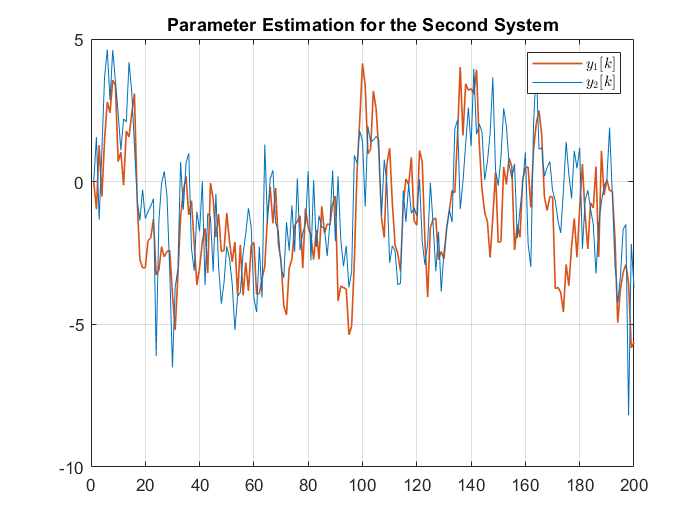

noises_plot

**Figura 1: **Sinais de saída $y_1(t)$ e $y_2(t)$ gerados. 

A estimativa dos parâmetros foi obtida utilizando o método de mínimos quadrados na formulação descrita neste documento. O sistema com saída descrito por: 


$$y(t) = u(t-1) +0.8y(t-1) + e(t-1)$$


Como previamente demonstrado na seção Avaliação Téorica - Modelo I, um erro de medição gaussiano não influencia na estimação dos parâmetros. Dessa forma, como esperado, a estimação do vetor de parâmetros tende a melhorar com o tempo. O resultado pode ser observado na Figura 2 referente ao sistema 1. Os parâmetros $â $ e $\hat b$ são estimados corretamente, mesmo com a presença do erro $e(t-1)$. Este resultado já era apontado pela demonstração detalhada na seção de Desenvolvimento. 

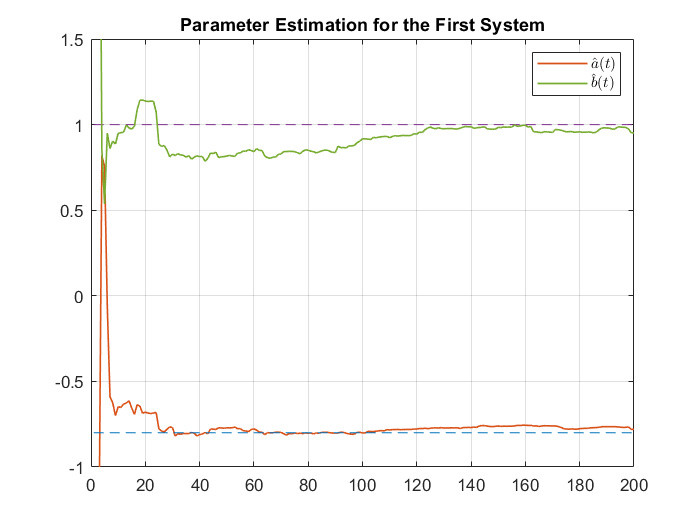

estimatives_plot

**Figura 2: **Estimação dos parâmetros $\hat a$ e $\hat b$ para o sistema 1. 

Com relação ao sistema II, como o sinal ruidoso é do tipo $z(t) = e(t)-e(t-1)$, ele se configura como um ruído não gaussiano. Sendo assim, as demonstrações presentes na seção Avaliação Teórica - Modelo II apontam que o ruído compromete a estimativa, e isto pode ser confirmado ao visualizar a Figura 3. O método de mínimos quadrados não é capaz de prover uma estimativa satisfatória dos parâmetros do sistema. 

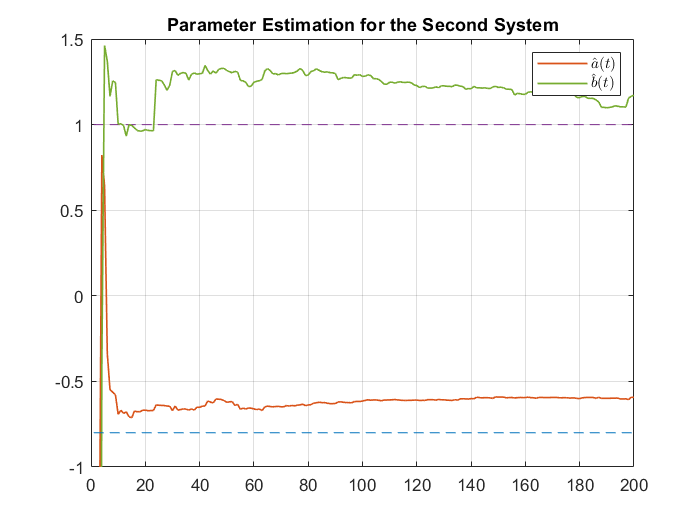

estimatives_plot_2

**Figura 3: **Estimação dos parâmetros $\hat a$ e $\hat b$ para o sistema 2. 

## Referências

[1]   L. LJUNG.** System Identification: Theory for the User **Courier Corporation, 2008. ISBN 0486462781.